# ODE Lab: Creating your own ODE solver in MATLAB

In this lab, you will write your own ODE solver for the Improved Euler method (also known as the Heun method), and compare its results to those of `ode45`.

You will also learn how to write a function in a separate m-file and execute it.

Opening the m-file lab3.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are six (6) exercises in this lab that are to be handed in on the due date. Write your solutions in the template, including appropriate descriptions in each step. Save the .m files and submit them online on Quercus.

## Student Information

Student Name: Qingyuan Wu

Student Number: 1007001664

## Creating new functions using m-files.

Create a new function in a separate m-file:

Specifics: Create a text file with the file name f.m with the following lines of code (text):

Now MATLAB can call the new function f (which simply accepts 3 numbers and adds them together). To see how this works, type the following in the matlab command window: sum = f(1,2,3)

## Exercise 1

Objective: Write your own ODE solver (using the Heun/Improved Euler Method).

Details: This m-file should be a function which accepts as variables (t0,tN,y0,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, y0 is the initial condition of the ODE, and h is the stepsize. You may also want to pass the function into the ODE the way `ode45` does (check lab 2).

Note: you will need to use a loop to do this exercise. You will also need to recall the Heun/Improved Euler algorithm learned in lectures. 

## Exercise 2

Objective: Compare Heun with `ode45`.

Specifics: For the following initial-value problems (from lab 2, exercises 1, 4-6), approximate the solutions with your function from exercise 1 (Improved Euler Method). Plot the graphs of your Improved Euler Approximation with the `ode45` approximation.

% (a) |y' = y tan t + sin t, y(0) = -1/2| from |t = 0| to |t = pi|
%
% (b) |y' = 1 / y^2 , y(1) = 1| from |t=1| to |t=10|
%
% (c) |y' =  1 - t y / 2, y(0) = -1| from |t=0| to |t=10|
%
% (d) |y' = y^3 - t^2, y(0) = 1| from |t=0| to |t=1|


% Comment on any major differences, or the lack thereof. You do not need
% to reproduce all the code here. Simply make note of any differences for
% each of the four IVPs.

% a) the graphs were very similar with no diverging in the interval [0,pi]
% b) the graphs were very similar with no diverging in the interval [1,10].
% In fact, the IEM and ode45 solutions became almost identical after around
% t=4.
% c) the graphs were very similar with no diverging within the given
% interval. However, ode45 uses a much coarser step size, so differences
% between the two graphs were noticeable between t=2 and t=4.
% d) the graph for the solution using Improved Euler's blew up to infinity
% at around t=0.5. However, the solution using ode45 remained low.

## Exercise 3

Objective: Use Euler's method and verify an estimate for the global error.

Details: 

(a) Use Euler's method (you can use euler.m from iode) to solve the IVP

`y' = 2 t sqrt( 1 - y^2 ) , y(0) = 0`

from `t=0` to `t=0.5`.

(b) Calculate the solution of the IVP and evaluate it at `t=0.5`.

(c) Read the attached derivation of an estimate of the global error for Euler's method. Type out the resulting bound for En here in a comment. Define each variable.

(d) Compute the error estimate for `t=0.5` and compare with the actual error.

(e) Change the time step and compare the new error estimate with the actual error. Comment on how it confirms the order of Euler's method.

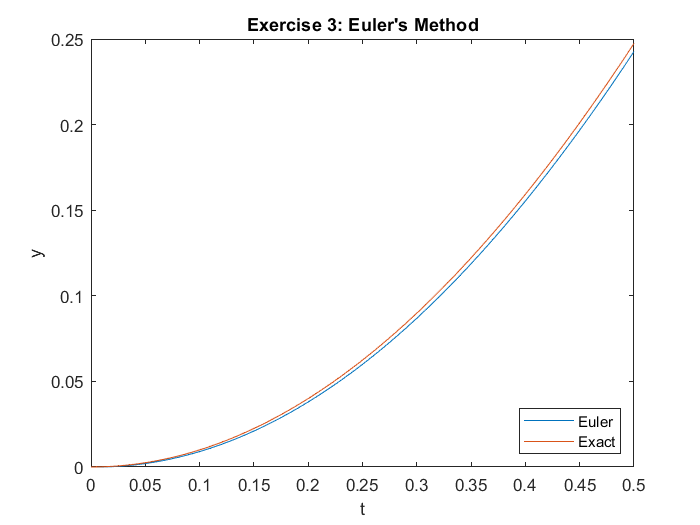

% b) Analytic solution:
% dy/sqrt(1-y^2) = (2t)dt;
% arcsin(y) = t^2 + C => C = 0
% y = sin(t^2);
% sin(0.5^2) = 0.2474;
% c) dt is the time step, n is the number of steps, M is the upper bound
% for f(t,y), df/dt and df/dy for t between 0 and 0.5.

% Find bound of global error:
% Take sum of (1+Mdt)^i, for i from 0 to n-1. This is bounded above by (exp(M*dt*n)-1)/(Mdt).
% Multiplying this by the (M+M^2)/2*(dt)^2, we get:
% Global error <= dt(exp(M*dt*n)-1)(1+M)/2

% d) error estimate for t=0.5. Time step = 0.01.
% dt*n = 0.5. Find M:
% f = y' = 2t*sqrt(1-y^2) -> M = 1
% f_y = df/dy = 2sqrt(1-y^2) - 2t/sqrt(1-y^2) * f -> M = 2
% f_t = df/dt = 2sqrt(1-y^2) -> M = 2
% Therefore, M = 2 as the upper bound for all three.

% E_n <= dt(1+M)(exp(M*dt*n)-1)/2
% = 0.01*(1+2)*(exp(2*0.5)-1)/2
% = 0.02577;

% actual error = abs(0.247404-0.242672) = 0.004732
% the actual error is less than the calculated error bound, which is
% expected. 

% e) Decrease the step size from 0.01 to 0.001:
% actual error = abs(0.247404-0.246932) = 0.000472
% this is roughly 1/10 of the error with h = 0.01. From this, we can see
% that the error scales linearly with the step size. This is indeed the
% case for Euler's method, which is of order 1.

t0 = 0;
y0 = 0;
tN = 0.5;
h = 0.01; % time step

yd = @(t,y) 2*t*sqrt(1-y^2); % this must be (t,y) for ode45 to work
[t,y] = EM(yd, t0, tN, y0, h);

plot(t,y);
hold on;
x_exact = linspace(t0, tN, 100);
y_exact = sin(x_exact.^2);
plot(x_exact, y_exact);

xlabel("t");
ylabel("y");
title("Exercise 3: Euler's Method")
legend("Euler", "Exact","location","southeast");
hold off;

## Adaptive Step Size

As mentioned in lab 2, the step size in `ode45` is adapted to a specific error tolerance.

The idea of adaptive step size is to change the step size `h` to a smaller number whenever the derivative of the solution changes quickly. This is done by evaluating f(t,y) and checking how it changes from one iteration to the next.

## Exercise 4

Objective: Create an Adaptive Euler method, with an adaptive step size `h`.

Details: Create an m-file which accepts the variables `(t0,tN,y0,h)`, as in exercise 1, where `h` is an initial step size. You may also want to pass the function into the ODE the way `ode45` does.

Create an implementation of Euler's method by modifying your solution to exercise 1. Change it to include the following:

(a) On each timestep, make two estimates of the value of the solution at the end of the timestep: `Y` from one Euler step of size `h` and `Z` from two successive Euler steps of size `h/2`. The difference in these two values is an estimate for the error.

(b) Let `tol=1e-8` and `D=Z-Y`. If `abs(D)<tol`, declare the step to be successful and set the new solution value to be `Z+D`. This value has local error `O(h^3)`. If `abs(D)>=tol`, reject this step and repeat it with a new step size, from (c).

(c) Update the step size as `h = 0.9*h*min(max(tol/abs(D),0.3),2)`.

Comment on what the formula for updating the step size is attempting to achieve.

% See adaptiveEM.m for function, or at the end of this file.

% Updating the step size is decreasing h to get a more accurate
% solution. The most that h can be decreased by is h_new = 0.9*0.3h =
% 0.27h. This will happen when tol/abs(D) <= 0.3, or when the error, abs(D)
% is greater than or equal to 1e-8/0.3. The least that h can be decreased
% by is h_new = 0.9h. This occurs when tol = abs(D). In general, h is
% decreased according to how much bigger the error is greater than tol.

## Exercise 5

Objective: Compare Euler to your Adaptive Euler method.

Details: Consider the IVP from exercise 3.

(a) Use Euler method to approximate the solution from `t=0` to `t=0.75` with `h=0.025`.

(b) Use your Adaptive Euler method to approximate the solution from `t=0` to `t=0.75` with initial `h=0.025`.

(c) Plot both approximations together with the exact solution.

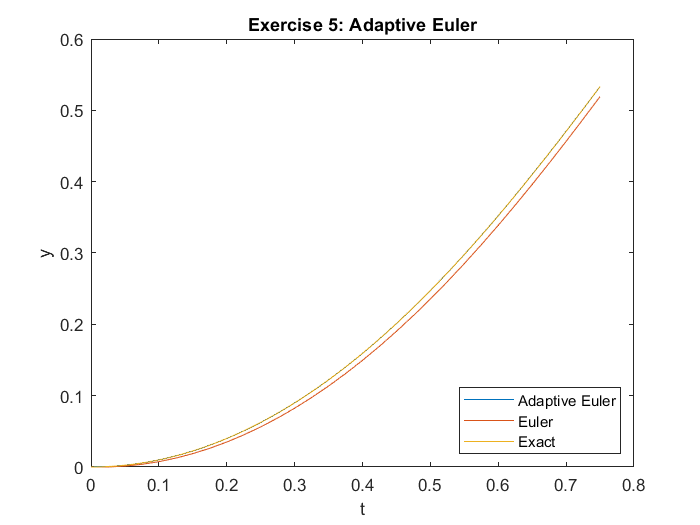

% y' = 2t*sqrt(1-y^2)
t0 = 0;
y0 = 0;
tN = 0.75;
h = 0.025;
f = @(t,y) 2*t*sqrt(1-y^2);
[t1,y1] = adaptiveEM(f, t0, tN, y0, h);
x_exact = linspace(t0, tN, 100);
y_exact = sin(x_exact.^2);
[t2,y2] = EM(f, t0, tN, y0, h);
plot(t1, y1, t2, y2, x_exact, y_exact);
xlabel("t");
ylabel("y");
title("Exercise 5: Adaptive Euler");
legend("Adaptive Euler", "Euler", "Exact", "location","southeast");


% Note that you cannot see the plot for adaptive Euler's method since the
% solution is too close to the exact solution.

## Exercise 6

Objective: Problems with Numerical Methods.

Details: Consider the IVP from exercise 3 (and 5).

(a) From the two approximations calculated in exercise 5, which one is closer to the actual solution (done in 3.b)? Explain why.

(b) Plot the exact solution (from exercise 3.b), the Euler's approximation (from exercise 3.a) and the adaptive Euler's approximation (from exercise 5) from `t=0` to `t=1.5`.

(c) Notice how the exact solution and the approximations become very different. Why is that? Write your answer as a comment.

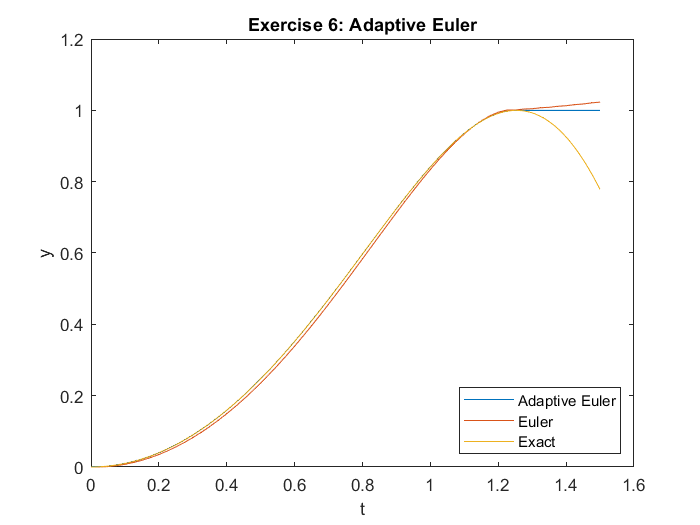

% 6a: the adaptive Euler's method is much closer to the exact solution
% than the standard Euler's method. This is due to the adaptive step
% size which requires that the local error is less than 1e-8, a very small
% number. In fact, without zooming in you can't even tell the difference
% between the adaptive EM and the exact solution.

% y' = 2t*sqrt(1-y^2)
t0 = 0;
y0 = 0;
tN = 1.5;
h = 0.025;
f = @(t,y) 2*t*sqrt(1-y^2);
[t1,y1] = adaptiveEM(f, t0, tN, y0, h);
x_exact = linspace(t0, tN, 100);
y_exact = sin(x_exact.^2);
[t2,y2] = EM(f, t0, tN, y0, h);
plot(t1, y1, t2, y2, x_exact, y_exact);
xlabel("t");
ylabel("y");
title("Exercise 6: Adaptive Euler");
legend("Adaptive Euler", "Euler", "Exact","location","southeast");


% 6c: the solutions become very different because at the point of zero
% slope near t=1.25, the Euler's Method approximation continues straight in
% a horizontal line. This means that the solution diverges from the exact
% solution. The adaptive step size solution diverges with the Euler's
% Method approximation since its metric for accuracy is the difference
% between improved Euler's approximations with varying step sizes. This
% condition does not guarantee that the solution remains close to the exact
% solution.

% Note that you cannot initially see the plot for adaptive Euler's method since the
% solution is too close to the exact solution. Once the solutions begin to
% diverge after 1.3, all three methods become visible.

% Functions:
% These can also be found in the other .m files

function [t,y] = IEM(f,t0,tN,y0,h)
    t = t0:h:tN;
    y = zeros(length(t), 1)';
    y(1) = y0;
    for i = 1:length(t)-1
        y(i+1) = y(i) + h/2*(f(t(i), y(i)) + f(t(i+1), y(i)+h*f(t(i),y(i))));
    end
end

function [t,y] = EM(f,t0,tN,y0,h)
    t = t0:h:tN;
    y = zeros(length(t), 1)';
    y(1) = y0;
    for i = 1:length(t)-1
        y(i+1) = y(i) + h*f(t(i), y(i));
    end
end

function [t,y] = adaptiveEM(f,t0,tN,y0,h)
    t = [];
    y = [];
    y(1) = y0;
    t(1) = t0;
    i = 1;
    while t(i) < tN
        Y = y(i) + h/2*(f(t(i), y(i)) + f(t(i)+h, y(i)+h*f(t(i),y(i))));
        
        Z_half = y(i) + h/4*(f(t(i), y(i)) + f(t(i)+h, y(i)+h*f(t(i),y(i))));
        Z = Z_half + h/4*(f(t(i)+h,Z_half) + f(t(i)+2*h, Z_half + h/2*f(t(i)+2*h,Z_half)));
        tol = 1e-8;
        D = Z-Y;
        
        if abs(D) < tol
            y(i+1) = Z-D; % local error O(h^3)
            t(i+1) = t(i)+h;
            i = i + 1;
        else
           h = 0.9*h*min(max(tol/abs(D),0.3),2);
        end    
    end
end